clear;clc;

- **题（1）**

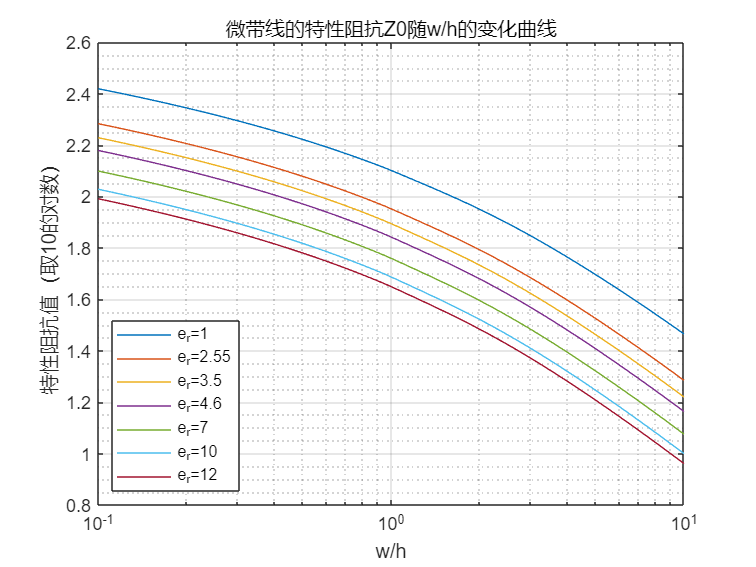

%%%%%%%%%%%%%%%%%%%实验条件%%%%%%%%%%%%%%%%%%%
wh=logspace(-1,1);%logspace(a,b)生成一个由在 10^a 和 10^b（10 的 N 次幂）之间的 50 个对数间距点组成的行向量 y。logspace 函数对于创建频率向量特别有用。
e_r=[1 2.55 3.5 4.6 7 10 12];
t=0;
h=0.001;%h取1mm
%%%%%%%%%%%%%%%%%%%初始化%%%%%%%%%%%%%%%%%%%%
Z01=zeros(1,length(wh));
Z02=zeros(1,length(wh));
Z03=zeros(1,length(wh));
Z04=zeros(1,length(wh));
Z05=zeros(1,length(wh));
Z06=zeros(1,length(wh));
Z07=zeros(1,length(wh));
eps_eff1=zeros(1,length(wh));
eps_eff2=zeros(1,length(wh));
eps_eff3=zeros(1,length(wh));
eps_eff4=zeros(1,length(wh));
eps_eff5=zeros(1,length(wh));
eps_eff6=zeros(1,length(wh));
eps_eff7=zeros(1,length(wh));
%%%%%%%%%%%计算特性阻抗和有效介电常数%%%%%%%%%%%
for i=1:length(wh)
    [Z01(i),eps_eff1(i)]=Z0cal_mstrip(wh(i),e_r(1),t,h);
    [Z02(i),eps_eff2(i)]=Z0cal_mstrip(wh(i),e_r(2),t,h);
    [Z03(i),eps_eff3(i)]=Z0cal_mstrip(wh(i),e_r(3),t,h);
    [Z04(i),eps_eff4(i)]=Z0cal_mstrip(wh(i),e_r(4),t,h);
    [Z05(i),eps_eff5(i)]=Z0cal_mstrip(wh(i),e_r(5),t,h);
    [Z06(i),eps_eff6(i)]=Z0cal_mstrip(wh(i),e_r(6),t,h);
    [Z07(i),eps_eff7(i)]=Z0cal_mstrip(wh(i),e_r(7),t,h);
end
%%%%%%%%%%%绘制图像%%%%%%%%%%%
figure(1);
semilogx(wh,log10(Z01),wh,log10(Z02),wh,log10(Z03),wh,log10(Z04),wh,log10(Z05),wh,log10(Z06),wh,log10(Z07));
title('微带线的特性阻抗Z0随w/h的变化曲线');
xlabel('w/h');
ylabel('特性阻抗值（取10的对数）');
lgd=legend('e_r=1','e_r=2.55','e_r=3.5','e_r=4.6','e_r=7','e_r=10','e_r=12');
lgd.Location = 'southwest';
grid on; grid minor;

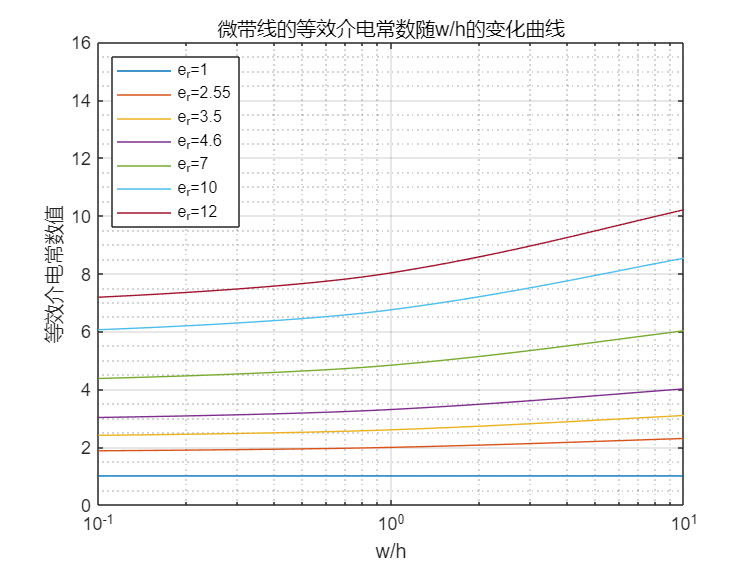


figure(2);
semilogx(wh,eps_eff1,wh,eps_eff2,wh,eps_eff3,wh,eps_eff4,wh,eps_eff5,wh,eps_eff6,wh,eps_eff7);
lgd=legend('e_r=1','e_r=2.55','e_r=3.5','e_r=4.6','e_r=7','e_r=10','e_r=12');
lgd.Location = 'northwest';
ylim([0 16]);
title('微带线的等效介电常数随w/h的变化曲线');
xlabel('w/h');
ylabel('等效介电常数值');
grid on; grid minor;

- **题（2）**

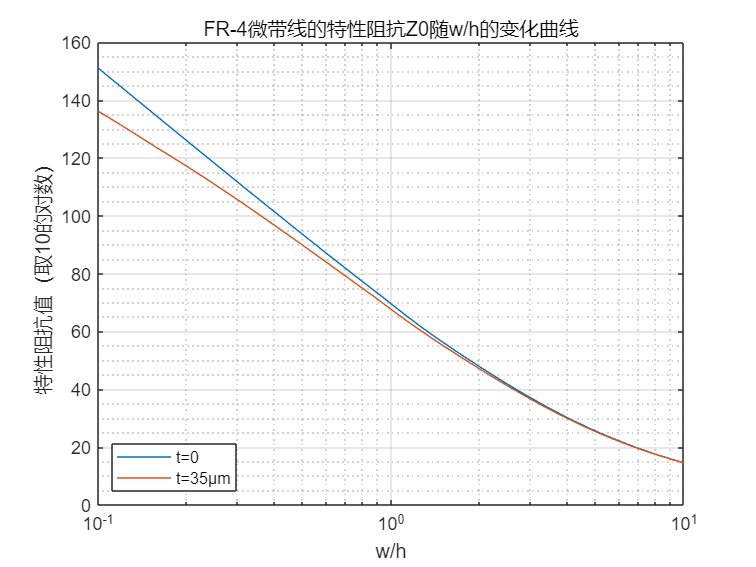

%%%%%%%%%%%%%%%%%%%实验条件%%%%%%%%%%%%%%%%%%%
t1=0;
t2=35*1e-6;
h=0.001;
er_FR4=4.6;
%%%%%%%%%%%%%%%%%%%初始化%%%%%%%%%%%%%%%%%%%%
Z08=zeros(1,length(wh));
Z09=zeros(1,length(wh));
eps_eff8=zeros(1,length(wh));
eps_eff9=zeros(1,length(wh));
%%%%%%%%%%%计算特性阻抗和有效介电常数%%%%%%%%%%%
for i=1:length(wh)
    [Z08(i),eps_eff8]=Z0cal_mstrip(wh(i),er_FR4,t1,h);
    [Z09(i),eps_eff9]=Z0cal_mstrip(wh(i),er_FR4,t2,h);
end
%%%%%%%%%%%绘制图像%%%%%%%%%%%
figure(3)
semilogx(wh,Z08,wh,Z09);
title('FR-4微带线的特性阻抗Z0随w/h的变化曲线');
xlabel('w/h');
ylabel('特性阻抗值（取10的对数）');
lgd=legend('t=0','t=35μm');
lgd.Location = 'southwest';
grid on; grid minor;

- **题（3）**

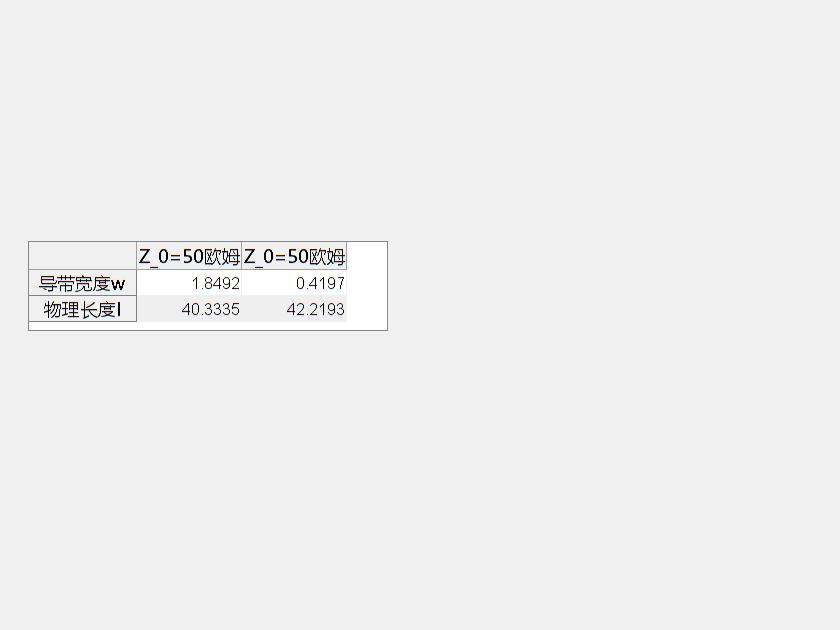

%%%%%%%%%%%计算导带宽度和物理长度%%%%%%%%%%%
lamda0=300000000/1000000000;% 波长
wh1=whcal_mstrip(50,er_FR4);
w1=wh1*h*1000;
[Z010,eps_eff10]=Z0cal_mstrip(wh1,er_FR4,0,h);
L1=1000*lamda0/sqrt(eps_eff10)/4;% 由电长度得到物理长度
wh2=whcal_mstrip(100,er_FR4);
w2=wh2*h*1000;
[Z011,eps_eff11]=Z0cal_mstrip(wh2,er_FR4,0,h);
L2=1000*lamda0/sqrt(eps_eff11)/4;% 由电长度得到物理长度
%%%%%%%%%%%绘制表格%%%%%%%%%%%
fig=figure;
data={w1,w2;L1,L2};
Table= uitable('Data', data, ...
    'ColumnName', {'Z_0=50欧姆', 'Z_0=50欧姆'}, ... % 设置列名
    'RowName',{'导带宽度w','物理长度l'}, ... % 设置表格的位置和大小
    'Position', [20 200 240 60]);

- 函数Z0cal_mstrip，用于计算微带线的特性阻抗和有效介电常数

function [Z0,eps_eff]=Z0cal_mstrip(wh,er,t,h)
%%%%%%%导带厚度t为0的情况%%%%%%%
if t==0
    if wh<=1
        Z0a=59.952.*log(8*wh.^(-1)+0.25.*wh);
        q=0.5+0.5*((1+12.*wh.^(-1)).^(-0.5)+0.041*(1-wh).^2);
        eps_eff=1+q.*(er-1);
        Z0=Z0a/sqrt(eps_eff);
    else
        Z0a=119.904*pi./(wh+2.42-0.44.*wh.^(-1)+(1-wh.^(-1)).^6);
        q=0.5+0.5*((1+12.*wh.^(-1)).^(-0.5));
        eps_eff=1+q.*(er-1);
        Z0=Z0a/sqrt(eps_eff);
    end
%%%%%%%导带厚度t不为0的情况%%%%%%%
else
    %we/h的修正公式
    if wh>=1/2/pi
        wh1=wh+t/pi/h.*(1+log(2*h/t));
    else
        wh1=wh+t/pi/h.*(1+log(4*pi*wh*h/t));
    end

    if wh1<=1
        Z0a=59.952.*log(8*wh1.^(-1)+0.25.*wh1);
        q=0.5+0.5*((1+12.*wh1.^(-1)).^(-0.5)+0.041*(1-wh1).^2);
        eps_eff=1+q.*(er-1);
        Z0=Z0a/sqrt(eps_eff);
    else
        Z0a=119.904*pi./(wh1+2.42-0.44.*wh1.^(-1)+(1-wh1.^(-1)).^6);
        q=0.5+0.5*((1+12.*wh1.^(-1)).^(-0.5));
        eps_eff=1+q.*(er-1);
        Z0=Z0a/sqrt(eps_eff);
    end
end
end

- 函数whcal_mstrip，由特性阻抗和相对介电长度设计出需要的宽长比

function wh = whcal_mstrip(Z0,er)
if Z0>44-2*er
    A=Z0.*sqrt(2.*(er+1))/119.9+(er-1)./2./(er+1).*(log(pi/2)+log(4/pi)./er);
    wh=1./(exp(A)./8-1/4./exp(A));
else
    B=59.95*pi*pi./Z0./sqrt(er);
    wh=2/pi.*(B-1-log(2.*B-1))+(er-1)/pi./er.*(log(B-10.293-0.517./er));
end
end